## Problem 1

**a)**

Two lattice branches, one optical and one acoustic.

**b) **


$$\omega^2=\gamma\frac{M_A+M_B}{M_AM_B}\pm\frac{\gamma}{M_AM_B}\sqrt{(M_A+M_B)^2-4(M_AM_B)\sin(\frac{ka}{2})^2}$$


clc
clear
close all

a = 1;
gamma = 1;
k = linspace(-pi/a, pi/a, 100);
w_plus = zeros(1, length(k));
w_minus = zeros(1, length(k));


$$M_A/M_B = 1$$


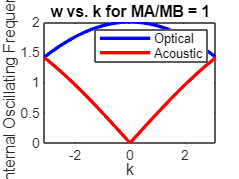

MA = 1;
MB = 1;

w_plus = gamma * (MA + MB) / (MA * MB) + (gamma / (MA * MB)) * ...
    sqrt((MA + MB) ^ 2 - 4 * MA * MB * sin(k * a / 2) .^ 2);
w_minus = gamma * (MA + MB) / (MA * MB) - (gamma / (MA * MB)) * ...
    sqrt((MA + MB) ^ 2 - 4 * MA * MB * sin(k * a / 2) .^ 2);

figure;
plot(k, sqrt(w_plus), 'b-', 'LineWidth', 2);
hold on;
plot(k, sqrt(w_minus), 'r-', 'LineWidth', 2);
ylabel('Internal Oscillating Frequency');
xlabel('k');
title('w vs. k for MA/MB = 1');
legend('Optical', 'Acoustic');


$$M_A/M_B = 10$$


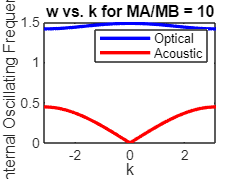

MA = 10;
MB = 1;

w_plus = gamma * (MA + MB) / (MA * MB) + (gamma / (MA * MB)) * ...
    sqrt((MA + MB) ^ 2 - 4 * MA * MB * sin(k * a / 2) .^ 2);
w_minus = gamma * (MA + MB) / (MA * MB) - (gamma / (MA * MB)) * ...
    sqrt((MA + MB) ^ 2 - 4 * MA * MB * sin(k * a / 2) .^ 2);

figure;
plot(k, sqrt(w_plus), 'b-', 'LineWidth', 2);
hold on;
plot(k, sqrt(w_minus), 'r-', 'LineWidth', 2);
ylabel('Internal Oscillating Frequency');
xlabel('k');
title('w vs. k for MA/MB = 10');
legend('Optical', 'Acoustic');

**c)**


$$\left[\matrix{ M_A\omega^2-2\gamma & \gamma(1+e^{-ika}) \cr \gamma(1+e^{ika})  &M_B\omega^2-2\gamma} \right] \left[\matrix{u_n^A \cr u_n^B} \right] = 0$$



$$\frac{u_n^A}{u_n^B} = \frac{-\gamma(1+e^{-ika})}{M_A\omega^2-2\gamma}$$


**For Acoustic**


$$k\rightarrow0$$



$$\omega^2 = 0$$



$$\frac{u_n^A}{u_n^B} = \frac{(1+e^{0})}{2} = 1$$



$$k\rightarrow\frac{\pi}{a}$$



$$\frac{u_n^A}{u_n^B} = 0$$


**For Optical**


$$k\rightarrow0$$



$$\omega^2 = \frac{2\gamma(M_A+M_B)}{M_AM_B}$$



$$\frac{u_n^A}{u_n^B} = \frac{-(1+e^{0})}{\frac{2(M_A+M_B)}{M_B}-2} = \frac{-M_B}{M_A}$$



$$k\rightarrow\frac{\pi}{a}$$



$$\frac{u_n^A}{u_n^B} = 0$$
